% Housekeeping
clear
clc
close all

% Define the time horizon
T = 100;
tstep = 0.001;                              % Define a (fixed) time step
tspan_forward = 0 : tstep : T - 0.0000001; % Define the time instances for forward simulation

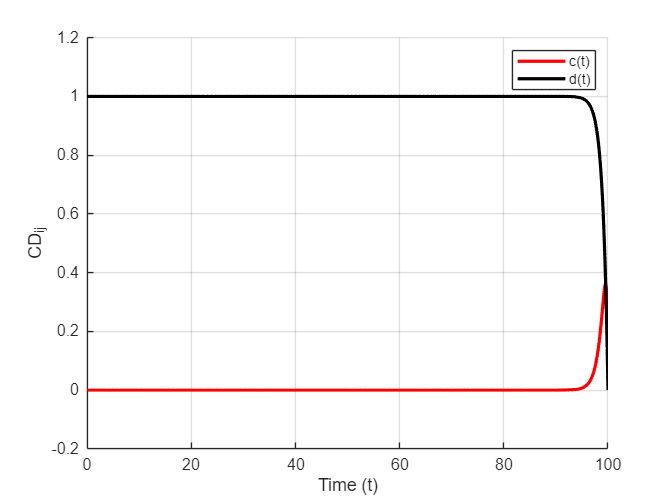

% Solve differential Riccati equations backwards in time
tspan_backward = flip(tspan_forward);

% Define the terminal conditions (the "initial" conditions for backward integration)
CD_T = [0 ; 0];

% Use ode45 to solve the ODEs for c and d backwards in time
[t, CD_backward] = ode45(@odefun, tspan_backward, CD_T);

% Flip the ontained solution to save and plot if forward in time
CD_forward = flipud(CD_backward);


% Plot the solution for c,d
figure;
hold on; 
plot(tspan_forward, CD_forward(:,1), 'r', 'LineWidth', 2);
plot(tspan_forward, CD_forward(:,2), 'k', 'LineWidth', 2);
hold off; 

xlabel('Time (t)');
ylabel('CD_{ij}');
legend('c(t)', 'd(t)');
grid on; 

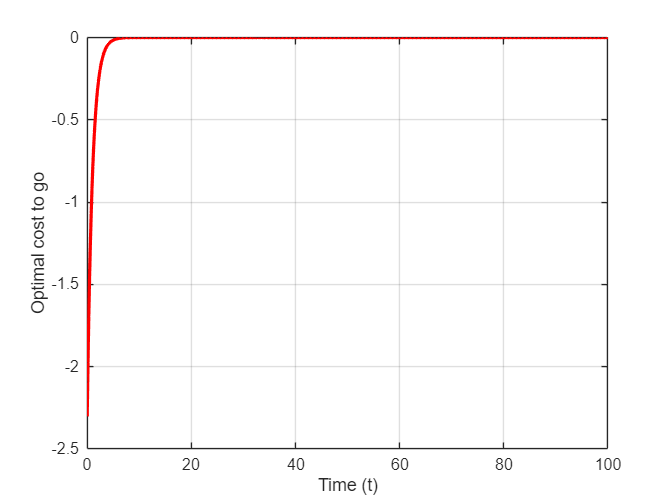


% Plot optimal cost to go
x0 = 10;

Opt = -exp(-tspan_forward') .* (CD_forward(:,1) + CD_forward(:,2) .* log(x0));

figure;
plot(tspan_forward, Opt , 'r', 'LineWidth', 2);

xlabel('Time (t)');
ylabel('Optimal cost to go');
grid on; 

function dCDdt = odefun(t, CD)

% CD(1) = c, CD(2) = d
c = CD(1);
d = CD(2);

% Define constant
a = 1;
rho = 1;
T = 100;

% Defines the system of differential equations from the Riccati equation
dCDdt = zeros(2, 1);
dCDdt(1) = (rho * c + log((1 / rho) * (1 - exp(-rho * T) * exp(rho * t))) - a * d + 1);
dCDdt(2) = (rho * d - 1);

end